# Wave to Blue

**************************************
**************************************
**************************************
**************************************
**************************************
**************************************
**************************************
**************************************


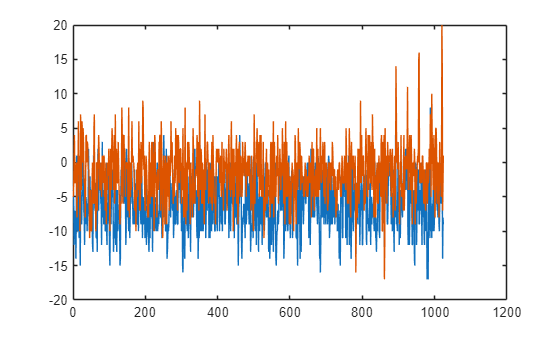

format long g

simDir = pwd;
datDir = [simDir '\..\zdata00' ];
wavFil = dir([datDir '\*.wav']);
allFil = dir(datDir);

[m,n] = size(wavFil);

hdr = py.xpy.blueWave.readHdrTemplate();

for ii = 1:m
    wavName = wavFil(ii).name;
    tmpName = strrep(lower(wavName),'wav','tmp');
    ai = audioinfo(wavName);
    midasTime = py.xpy.blueWave.fileName2MidasTime(wavName);
    fmtCode   = py.xpy.blueWave.getFormatCode(ai.BitsPerSample, ai.NumChannels);
    midasHeader = hdr;
    py.xpy.blueWave.changeSampleRate(midasHeader, ai.SampleRate);
    py.xpy.blueWave.changeFormatCode(midasHeader, fmtCode);
    py.xpy.blueWave.changeTimeCode(midasHeader, midasTime);
    if strcmpi(string(fmtCode),'CI')
        nBytes = ai.TotalSamples * 4;
    elseif strcmpi(string(fmtCode),'SI')
        nBytes = ai.TotalSamples * 2;
    end
    py.xpy.blueWave.changeNBytes(midasHeader, nBytes);
    py.xpy.blueWave.writeHeaderOnlyFile(tmpName, midasHeader);
    disp("**************************************")
    
    data = audioread(wavName, [1 1024], "native");
    plot(real(data));
    pause(1)


end

py.xpy.blueWave.displayHeader(midasHeader);

(b'B', b'L', b'U', b'E')
(b'E', b'E', b'E', b'I')
(b'E', b'E', b'E', b'I')
0
0
0
2017728
0
512.0
1033076736.0
1000
(b'C', b'I')
0
2381262884.0
0
0
0
0
0
0.0
0.0
0.0
0
(b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00')
(b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00')
(b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00')
(b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00')
(b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00')
(b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x00', b'\x10', b'\x00', b'\x00', b'\x00')
(b'I', b'O', b'=', b'X', b'M', b'P', b'Y', b'\x00', b'V', b'E')
(b'R', b'=', b'1', b'.', b'1', b'\x00', b' ', 

% py.xpy.blueWave.writeTheData(midasHeader,data)

# MISC

[https://en.wikipedia.org/wiki/Lockheed_C-130_Hercules](https://en.wikipedia.org/wiki/Lockheed_C-130_Hercules)

[https://www.google.com/maps/place/37%C2%B033'55.2%22N+77%C2%B001'28.3%22W/@37.5653399,-77.0258057,428](https://www.google.com/maps/place/37%C2%B033'55.2%22N+77%C2%B001'28.3%22W/@37.5653399,-77.0258057,428)

Turn radius [https://www.facebook.com/watch/?v=1091473448621766](https://www.facebook.com/watch/?v=1091473448621766)

about 45 degrees roll when turning. Let us call it 40

37.56523545180213, -77.02406623520642

Space X launch 25.996154039056375, -97.15433683778406